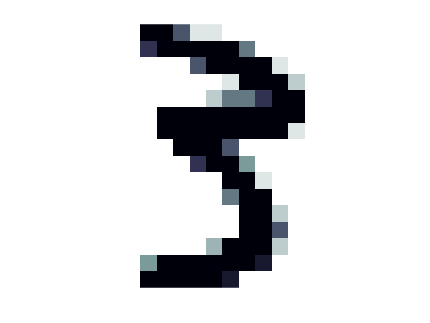

ans = 3

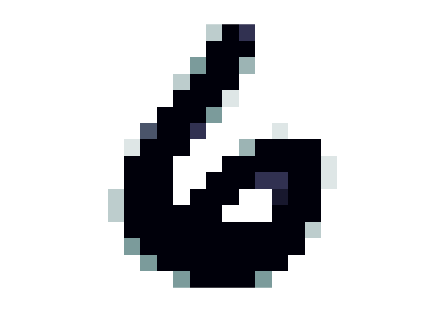

load zipdata.mat

% azip -> Training data
% dzip -> Result for training data
% testzip -> Test data
% dtest -> Result for test data

% Assignment: Implement the tangent distance classifier

% Att göra: 
% Blurra bilderna för bättre resultat
% För att ta bort de gråa områderna/bakgrunderna

[trainMatrix, testMatrix] = getTransformationMatrices(azip, testzip);


numberOfCorrect = 0;
for i = 1:length(dtest)
    if dtest(i) == classifyDigit(testzip(:,:,i),trainMatrix, azip, dzip, testMatrix(:,:,i))
        numberOfCorrect = numberOfCorrect+1;
    end
end

disp((numberOfCorrect/length(dtest))*100)

   96.8112



ans = 8.0625

function result = classifyDigit(numberToClassify, TrainTransform, trainingData, dzip, Te)
%UNTITLED2 Summary of this function goes here
%   Detailed explanation goes here
[m,n,k] = size(TrainTransform);
e = reshape(numberToClassify, 256,1);
minNorm = 20000;
savedIndex = 1;
for i = 1:k
    Tp = TrainTransform(:,:,i);
    A = [-Tp Te];
    b = reshape(trainingData(:,:,i), 256,1)-e;
    alpha = A\b;
    resultingNorm = norm(b-A*alpha);
    if (resultingNorm < minNorm)
        minNorm = resultingNorm;
        savedIndex = i;
    end
end
result = dzip(1,savedIndex);
end